## Solid Liquid Fit Example

First get the problemDefs etc by using an existing RasCAL1 project as usual (use original_DSPC_bilayer from the Rascal demo's folder).

First initialise RAT....

addRatPaths()

debug


Rather than populate the input classes manually, we build them from an existing Rascal project....

[problem,controls] = r1ToProblemDef('original_dspc_bilayer.mat')

problem =   problemDef with properties:

         experimentType: 'standard'
     experimentGeometry: 'substrate/liquid'
                nParams: 22
                 params: [5.0406 18.6723 3.4002e-06 21.0069 -3.4923e-07 5.9060 8.0722 19.8373 4.9879e-10 9.8423 1.0059e-06 6.6955 28.0113 10.0000 1.0000e-06 3.5028 17.1338 -1.6289e-07 16.4869 29.5219 99.9965 23.4506]
             paramNames: {1×22 cell}
            paramConstr: {1×22 cell}
          paramFitYesNo: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
           nBackgrounds: 2
            backgrounds: [2.0841e-06 3.1708e-06]
        backgroundNames: {'Background D2O'  'Background 2'}
       backgroundConstr: {[5.0000e-10 7.0000e-06]  [1.0000e-10 5.0000e-06]}
     backgroundFitYesNo: [1 1]
          nScalefactors: 2
           scalefactors: [0.1029 0.1432]
       scalefactorNames: {'Scalefactor 1'  'Scalefactor 2'}
      scalefactorConstr: {[0.0500 0.2000]  [0.0500 

controls =   controlsDef with properties:

            parallel: 'single'
           procedure: 'calculate'
    calcSldDuringFit: 'no'


Set up for running simplex...

controls.procedure = 'simplex';
controls.maxFunEvals = 1000

controls =   controlsDef with properties:

            parallel: 'single'
           procedure: 'simplex'
    calcSldDuringFit: 'no'
             display: 'iter'
                tolX: 1.0000e-06
              tolFun: 1.0000e-06
         maxFunEvals: 1000
             maxIter: 1000


Run the fit...

[outProblem,results] = RAT(problem,controls)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          7.01991         
     1           32          6.85788         initial simplex
     2           34          6.83468         reflect
     3           36           6.5426         expand
     4           37           6.5426         reflect
     5           38           6.5426         reflect
     6           40           6.5426         contract inside
     7           41           6.5426         reflect
     8           42           6.5426         reflect
     9           43           6.5426         reflect
    10           44           6.5426         reflect
    11           45           6.5426         reflect
    12           46           6.5426         reflect
    13           47           6.5426         reflect
    14           48           6.5426         reflect
    15           49           6.5426         reflect
    16           50           6.5426         reflect
    17           51           6.54

outProblem = struct with fields:
           ssubs: [2×1 double]
     backgrounds: [2×1 double]
         qshifts: [2×1 double]
    scalefactors: [2×1 double]
          nbairs: [2×1 double]
          nbsubs: [2×1 double]
     resolutions: [2×1 double]
    calculations: [1×1 struct]
     allSubRough: [2×1 double]


results = struct with fields:
    reflectivity: {2×1 cell}
      Simulation: {2×1 cell}
    shifted_data: {2×1 cell}
       layerSlds: {2×1 cell}
     sldProfiles: {2×1 cell}
       allLayers: {2×1 cell}


Plot out the results....

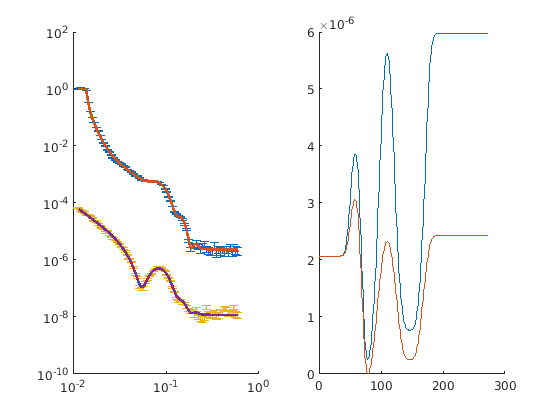

plotRefSLD(outProblem,results)